syms x1 x2 x3 x4 u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
T=0.1;% tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)  <- ESTADO NO LINEAL
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);

% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;

% Jacobiano simbólico
As=[diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4);...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4);...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4);...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)];

Bs=[diff(f1,u);diff(f2,u);diff(f3,u);diff(f4,u)];

C=[1 0 0 0];
D=[0];

% Ampliar A y B para acción integral
Aa = [As, zeros(4,1); -C, 0];
Bb = [Bs; 0];

%% Parámetros del controlador
zeta = 0.8;
tsdes = 2;
wn = 4.6 / (zeta * tsdes);
sistReferencia = tf([0 0 1],[1 2*zeta*wn wn^2]);
polosz = [pole(sistReferencia)' -1 -6 -5];

## Diseño del controlador Fuzzy


cpFIS = mamfis(...
    'NumInputs', 4, 'NumInputMFs', 3, ...
    'NumOutputs', 1, 'NumOutputMFs', 7, ...
    'AddRule', 'none');

#### Funciones de Membresia para la Posición del Pendulo

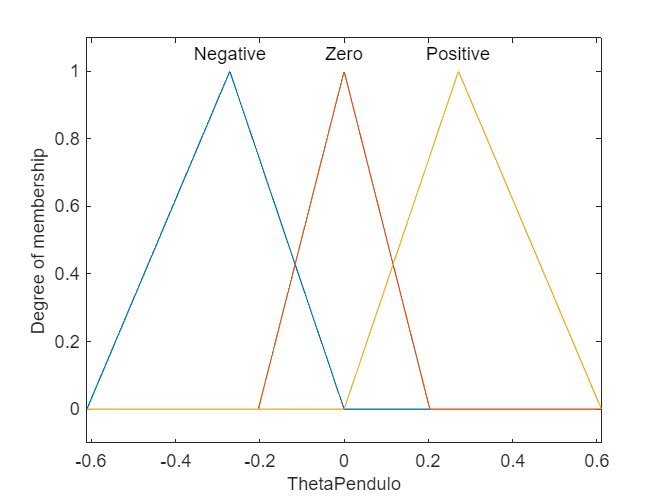

cpFIS.Inputs(1).Name = 'ThetaPendulo';
AngMax = deg2rad(35);
cpFIS. Inputs(1).Range = [-AngMax, AngMax];
% Función de membresía Negative (Trapezoidal)
cpFIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(1).MembershipFunctions(1).Type = 'trimf';
cpFIS.Inputs(1).MembershipFunctions(1).Parameters = AngMax/9*[-9, -4, 0];

% Función de membresía Zero (Triangular)
cpFIS.Inputs(1).MembershipFunctions(2).Name = 'Zero';
cpFIS.Inputs(1).MembershipFunctions(2).Type = 'trimf';
cpFIS.Inputs(1).MembershipFunctions(2).Parameters = AngMax/9*[-3, 0, 3];

% Función de membresía Positive (Trapezoidal)
cpFIS.Inputs(1).MembershipFunctions(3).Name = 'Positive';
cpFIS.Inputs(1).MembershipFunctions(3).Type = 'trimf';
cpFIS.Inputs(1).MembershipFunctions(3).Parameters = AngMax/9*[0, 4, 9];
figure;
plotmf(cpFIS, 'input', 1, 1000);

#### Funciones de Membresia para la Velocidad del Pendulo

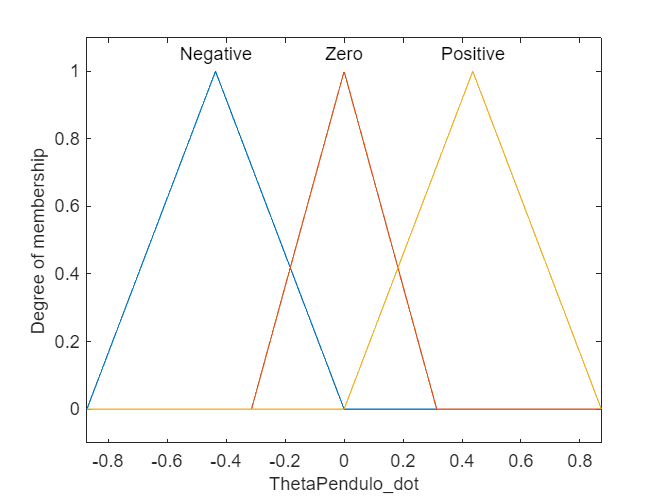

cpFIS.Inputs(2).Name = 'ThetaPendulo_dot';
VelAngMax = deg2rad(50);
cpFIS. Inputs(2).Range = [-VelAngMax, VelAngMax];

% Función de membresía Negative (Trapezoidal)
cpFIS.Inputs(2).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(2).MembershipFunctions(1).Type = 'trimf';
cpFIS.Inputs(2).MembershipFunctions(1).Parameters = VelAngMax/5*[-5, -2.5, 0];

% Función de membresía Zero (Triangular)
cpFIS.Inputs(2).MembershipFunctions(2).Name = 'Zero';
cpFIS.Inputs(2).MembershipFunctions(2).Type = 'trimf';
cpFIS.Inputs(2).MembershipFunctions(2).Parameters = VelAngMax/5*[-1.8, 0, 1.8];

% Función de membresía Positive (Trapezoidal)
cpFIS.Inputs(2).MembershipFunctions(3).Name = 'Positive';
cpFIS.Inputs(2).MembershipFunctions(3).Type = 'trimf';
cpFIS.Inputs(2).MembershipFunctions(3).Parameters = VelAngMax/5*[0, 2.5, 5];
figure;
plotmf(cpFIS, 'input', 2, 1000);

#### Funciones de Membresia para la Posición del Brazo

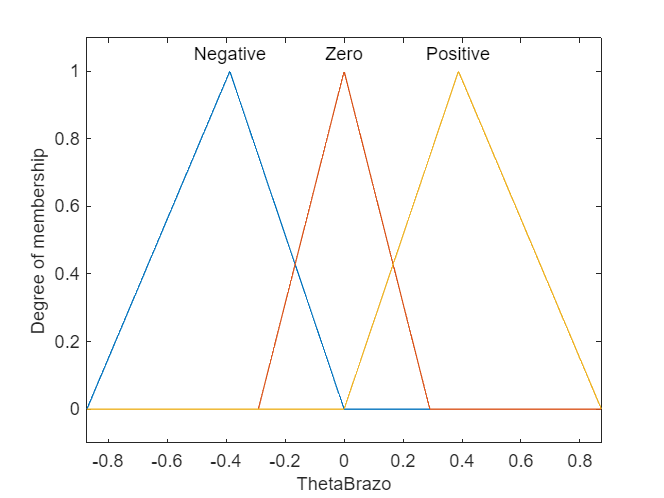

cpFIS.Inputs(3).Name = 'ThetaBrazo';
cpFIS. Inputs(3).Range = [-deg2rad(50), deg2rad(50)];
% Función de membresía Negative (Trapezoidal)
cpFIS.Inputs(3).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(3).MembershipFunctions(1).Type = 'trimf';
cpFIS.Inputs(3).MembershipFunctions(1).Parameters = deg2rad(50)/9*[-9, -4, 0];

% Función de membresía Zero (Triangular)
cpFIS.Inputs(3).MembershipFunctions(2).Name = 'Zero';
cpFIS.Inputs(3).MembershipFunctions(2).Type = 'trimf';
cpFIS.Inputs(3).MembershipFunctions(2).Parameters = deg2rad(50)/9*[-3, 0, 3];

% Función de membresía Positive (Trapezoidal)
cpFIS.Inputs(3).MembershipFunctions(3).Name = 'Positive';
cpFIS.Inputs(3).MembershipFunctions(3).Type = 'trimf';
cpFIS.Inputs(3).MembershipFunctions(3).Parameters = deg2rad(50)/9*[0, 4, 9];
figure;
plotmf(cpFIS, 'input', 3, 1000);

#### Funciones de Membresia para la Velocidad del Brazo

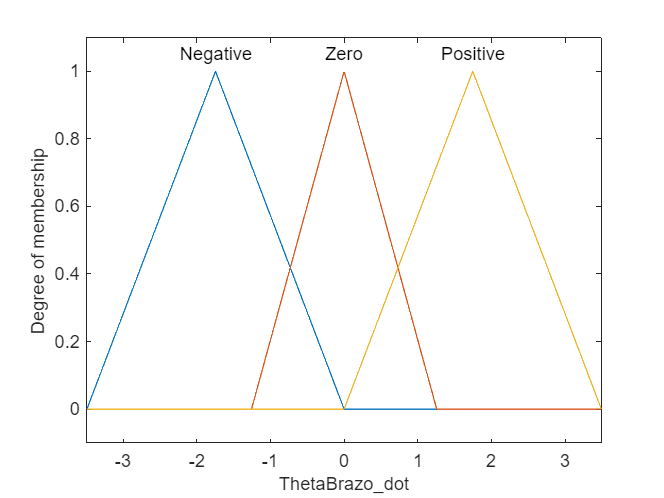

cpFIS.Inputs(4).Name = 'ThetaBrazo_dot';
cpFIS. Inputs(4).Range = [-deg2rad(200), deg2rad(200)];

% Función de membresía Negative (Trapezoidal)
cpFIS.Inputs(4).MembershipFunctions(1).Name = 'Negative';
cpFIS.Inputs(4).MembershipFunctions(1).Type = 'trimf';
cpFIS.Inputs(4).MembershipFunctions(1).Parameters = deg2rad(200)/5*[-5, -2.5, 0];

% Función de membresía Zero (Triangular)
cpFIS.Inputs(4).MembershipFunctions(2).Name = 'Zero';
cpFIS.Inputs(4).MembershipFunctions(2).Type = 'trimf';
cpFIS.Inputs(4).MembershipFunctions(2).Parameters = deg2rad(200)/5*[-1.8, 0, 1.8];

% Función de membresía Positive (Trapezoidal)
cpFIS.Inputs(4).MembershipFunctions(3).Name = 'Positive';
cpFIS.Inputs(4).MembershipFunctions(3).Type = 'trimf';
cpFIS.Inputs(4).MembershipFunctions(3).Parameters = deg2rad(200)/5*[0, 2.5, 5];
figure;
plotmf(cpFIS, 'input', 4, 1000);

### Funciones de Membresia para la Salida

#### Funciones de Membresia para la Fuerza

Se impementaron 7 fuerzas en diferentes rango para adaptar la salida respecto la mencionado en el proceso.

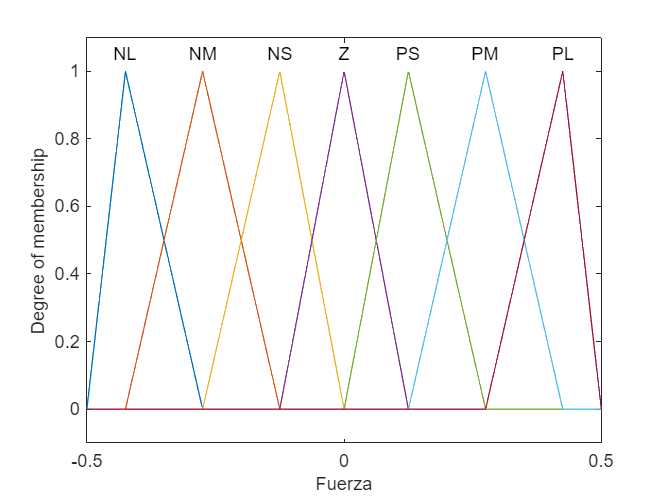

% Crear la salida 'Fuerza'
FM = 0.5;
cpFIS.Outputs(1).Name = 'Fuerza';
cpFIS.Outputs(1).Range = [-FM, FM];

% Definir funciones de pertenencia de la salida con trimf
cpFIS.Outputs(1).MembershipFunctions(1).Name = 'NL';  % Negativo Grande
cpFIS.Outputs(1).MembershipFunctions(1).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(1).Parameters = FM/20*[-20, -17, -11];

cpFIS.Outputs(1).MembershipFunctions(2).Name = 'NM';  % Negativo Medio
cpFIS.Outputs(1).MembershipFunctions(2).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(2).Parameters = FM/20*[-17, -11, -5];

cpFIS.Outputs(1).MembershipFunctions(3).Name = 'NS';  % Negativo Pequeño
cpFIS.Outputs(1).MembershipFunctions(3).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(3).Parameters = FM/20*[-11, -5, 0];

cpFIS.Outputs(1).MembershipFunctions(4).Name = 'Z';  % Cero
cpFIS.Outputs(1).MembershipFunctions(4).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(4).Parameters = FM/20*[-5, 0, 5];

cpFIS.Outputs(1).MembershipFunctions(5).Name = 'PS';  % Positivo Pequeño
cpFIS.Outputs(1).MembershipFunctions(5).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(5).Parameters = FM/20*[0, 5, 11];

cpFIS.Outputs(1).MembershipFunctions(6).Name = 'PM';  % Positivo Medio
cpFIS.Outputs(1).MembershipFunctions(6).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(6).Parameters =FM/20* [5, 11, 17];

cpFIS.Outputs(1).MembershipFunctions(7).Name = 'PL';  % Positivo Grande
cpFIS.Outputs(1).MembershipFunctions(7).Type = 'trimf';
cpFIS.Outputs(1).MembershipFunctions(7).Parameters = FM/20* [11, 17, 20];

figure;
plotmf(cpFIS, 'output', 1, 1000);

## Reglas del controlador

rules = [...
    "If ThetaBrazo is Negative then Fuerza is PS"; ...
    "If ThetaBrazo is Positive then Fuerza is NS"; ...
    "If ThetaBrazo is Zero then Fuerza is Z";...
    
    "If ThetaBrazo_dot is Negative then Fuerza is NS";...
    "If ThetaBrazo_dot is Positive then Fuerza is PS";...
    "If ThetaBrazo_dot is Zero then Fuerza is Z";...
    
    "If ThetaPendulo is Negative then Fuerza is PM";....
    "If ThetaPendulo is Positive then Fuerza is NM";...
    "If ThetaPendulo is Zero then Fuerza is Z";...

    "If ThetaPendulo_dot is Negative then Fuerza is NL";...
    "If ThetaPendulo_dot is Positive then Fuerza is PL";...
    "If ThetaPendulo_dot is Zero then Fuerza is Z";...
];
cpFIS = addRule(cpFIS, rules);


## Simulación

#### Parámetros

Tspan = 20;                % Tiempo final de simulación
Ts = 0.01;                  % Tiempo de muestreo
Ns = round(Tspan / Ts);     % Número de iteraciones
x0 = [1*pi/180; 0; 3*pi/180; 0];   % Condiciones iniciales
u = 0;                      % Valor inicial de la entrada
x_acc = zeros(4, Ns);
u_acc = zeros(1, Ns);
x3ref = 0;               % Referencia en posición de carro
x1ref = 0;
xmed = x0;

#### Implementación del controlador

controller = 0;
warning('off', 'all');
Noisy = 0;
evalfis(cpFIS, [0.6*(xmed(3)-x3ref), xmed(4), xmed(1)-x1ref, xmed(2)])

ans = -0.0571

for i = 1:Ns
    [~, x_out] = ode45(@(t, x) complex_rot_pend(t, x, [], controller), [0 Ts], x0);
    %[t, x] = ode45('pendinvert', Ts, x0, [], controller); % Solución del sistema
    xmed = x_out(end, :)';     % Medición de estados
    
    % Inyección de ruido en las mediciones a los 40 segundos
    % if Ts*i == 40
    %     noise_factor = 0.2;  % Factor de amplitud de ruido
    %     noise = noise_factor * randn(size(xmed));  % Ruido gaussiano
    %     xmed = xmed + noise;  % Agregar ruido a las mediciones
    % end
    
    desp = [x1ref; 0; x3ref; 0]; % Desplazamiento de estados
    xdesp = xmed - desp;   % Error de los estados respecto a la referencia
    
    % % Referencia de Posición
    Xref1(i) = x1ref;
    % 
    if Ts*i == 12
        x1ref = deg2rad(20);
    end


    x0 = xmed;
    xmed = xmed';
    x_acc(:, i) = xmed;
    controller = evalfis(cpFIS, [3.5*(x3ref-xmed(3)), 0.5*xmed(4), 0.35*(x1ref-xmed(1)),1.5*xmed(2)]);
    u_acc(:, i) = controller;

    % Actualizar variables de animación
    cart_pos = xmed(3);        % Posición del carro
    theta = xmed(1);           % Ángulo del péndulo
end
x_acc = x_acc';
% Tiempo de simulación y valores de x_3 y la referencia
t_acc=0:Ts:Tspan-Ts;

## Resultados

El ángulo del péndulo converge rápidamente a 0°, demostrando la capacidad del controlador para estabilizar el sistema de manera eficiente.

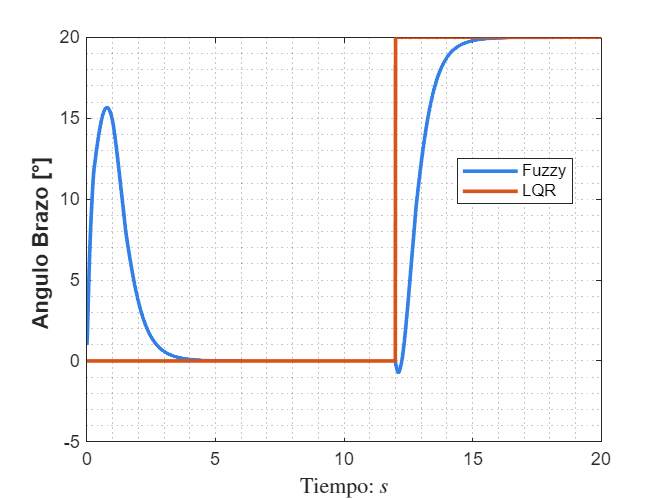

figure;
plot(t_acc, x_acc(:, 1)*180/pi, 'Color', [0.2, 0.5, 0.9], 'LineWidth', 2); 
hold on 
plot(t_acc, Xref1*180/pi, 'LineWidth', 2); 
hold off
grid minor;
xlabel("Tiempo: $s$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Angulo Brazo [°] ", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
legend('Fuzzy', 'LQR', 'Location', 'best');

Las oscilaciones iniciales de la velocidad angular son rápidamente amortiguadas, reflejando un control efectivo de las dinámicas del péndulo.

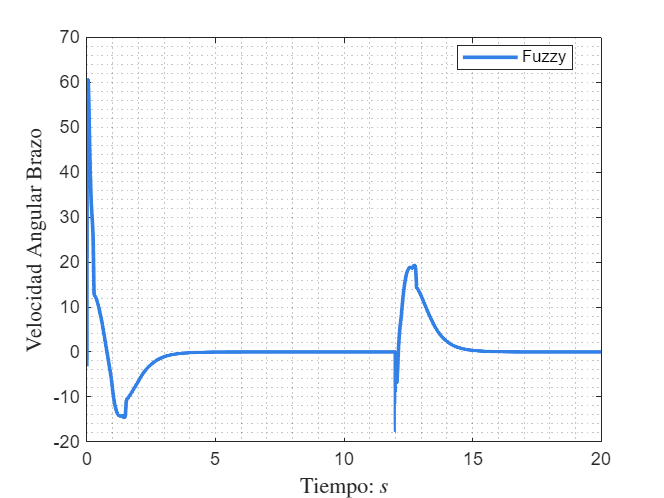

figure;
plot(t_acc, x_acc(:, 2)*180/pi, 'Color', [0.2, 0.5, 0.9], 'LineWidth', 2); 
grid minor
xlabel("Tiempo: $s$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Velocidad Angular Brazo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
legend('Fuzzy', 'LQR', 'Location', 'best');

El carro sigue la referencia establecida, con transiciones suaves y un error de posición mínimo incluso durante el cambio de referencia a los 20 segundos.

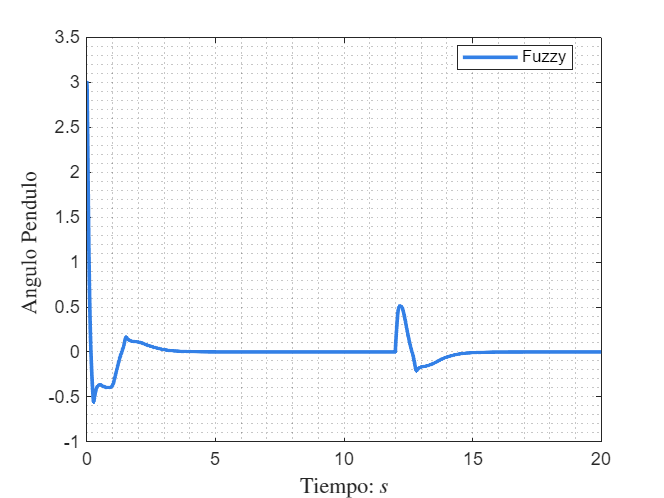

figure;
plot(t_acc,  x_acc(:, 3)*180/pi, 'Color', [0.2, 0.5, 0.9], 'LineWidth', 2); 
grid minor;
xlabel("Tiempo: $s$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Angulo Pendulo ", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
legend('Fuzzy', 'LQR', 'Referencia', 'Location', 'best');

La velocidad del carro se mantiene dentro de límites seguros, adaptándose a los cambios de referencia sin generar inestabilidades.

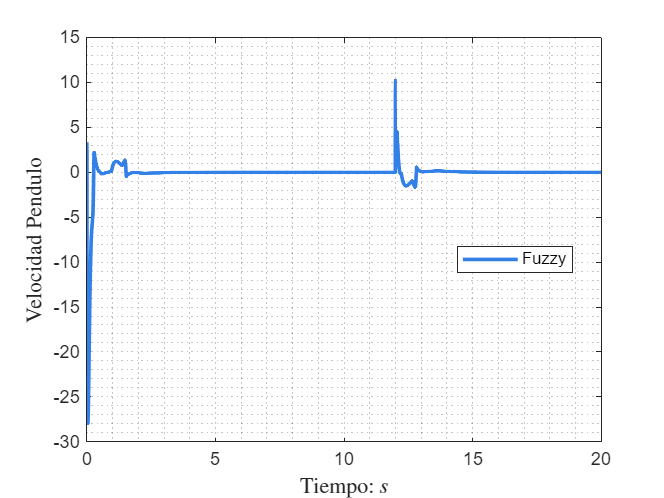

figure;
plot(t_acc,  x_acc(:, 4)*180/pi, 'Color', [0.2, 0.5, 0.9], 'LineWidth', 2); 
grid minor;
xlabel("Tiempo: $s$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Velocidad Pendulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
legend('Fuzzy', 'LQR', 'Location', 'best');

La fuerza aplica al sistema se puede ver que no es ruidosa y el diseño del controlador fuzzy permite mantener la estabilidad general del péndulo invertido, lo que demuestra la robustez del esquema implementado.

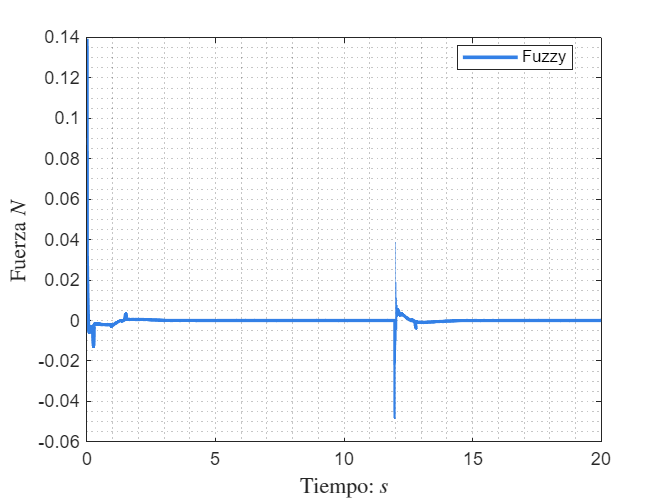

figure;
plot(t_acc, u_acc, 'Color', [0.2, 0.5, 0.9], 'LineWidth', 2); 
grid minor;
xlabel("Tiempo: $s$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Fuerza $N$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
legend('Fuzzy', 'LQR', 'Location', 'best');

## Conclusiones

Aunque el diseño del controlador difuso resulta relativamente sencillo de implementar, es crucial contar con un conocimiento detallado del sistema o planta que se desea controlar. Este conocimiento permite establecer reglas que prioricen las dinámicas más críticas del sistema y diseñar funciones de membresía adecuadas. Si las funciones de membresía no abarcan correctamente los rangos operativos del sistema, ajustar las ganancias asociadas a cada entrada del controlador puede volverse un desafío significativo, comprometiendo el desempeño y la estabilidad del sistema, dado que en este caso no se realizó LQR para facilitar la busqueda de estas ganacias se complicó un poco este proceso. Por ello, una etapa previa de análisis detallado del modelo del sistema y sus límites operativos es fundamental para garantizar un diseño efectivo del controlador.

Al compararar el controlador Fuzzy con el controlador LQR se pouede ver que es similar la señal de control que realizan, a los 40 segundos se ven diferencias porque es un ruido aleatorio para cada simulacion pero en general se parece la forma en que hace el control.

El controlador difuso diseñado logró estabilizar el péndulo invertido de manera eficiente, llevando el ángulo rápidamente a 0° y amortiguando las oscilaciones iniciales de la velocidad angular en un tiempo corto. Esto mostró la capacidad del controlador para manejar las dinámicas no lineales del sistema.

El carro respondió con precisión a las referencias establecidas, mostrando transiciones suaves y un error de posición mínimo. Esto refleja un diseño robusto de las reglas difusas y un adecuado manejo de las variables de estado del sistema.

La inclusión de ruido gaussiano en las mediciones no afectó significativamente la estabilidad del sistema. Esto demuestra que el controlador difuso es robusto frente a perturbaciones externas y mediciones ruidosas.

Se priorizó un control más fuerte sobre el ángulo del péndulo, mientras que las acciones sobre el carro se mantuvieron moderadas. Este balance permitió corregir la posición del sistema sin comprometer la estabilidad del péndulo.

Las funciones de membresía triangulares y trapezoidales utilizadas permitieron representar eficazmente los rangos operativos, mientras que las reglas del controlador generaron fuerzas precisas y adecuadas para contrarrestar las perturbaciones.

Aunque el diseño mostró gran efectividad, el ruido presente en la fuerza aplicada podría mejorarse mediante técnicas adicionales de suavizado o control adaptativo. Además, futuras se podrían explorar optimizaciones del controlador para mejorar el desempeño bajo condiciones más extremas.